# A Simple Factor Graph Example

## Introduction

The point of this notebook is to create a factor graph that demonstrates how factor graphs work.  I want the example to include some things that are a bit more tricky to understand with factor graphs, in particular dynamics and constant elements.  I also want the measurements to be fairly non-linear so things can be a good demonstration of factor graphs.

## Example System

### Dynamics

The system we will be considering is a simple unicycle-model robot.  The inputs to the system are $V$ and $\omega$, the linear and angular velocity, respectively. The robot lives in a 2-D work and has a heading, leading to a 3-element state vector $x_t = \pmatrix{x \cr y \cr \psi}$.  The dynamics for this vehicle are:

$\dot{x} = \pmatrix{V\cos\psi \cr V\sin\psi \cr \omega} + v$ where $V$ and $\omega$ are the inputs to the system and $v$ is a white, zero-mean Gaussian noise source distributed according to $\mathcal{N}(0,R)$, where $R$ is the covariance matrix of the noise.  To make the system more complex, we will sometimes add an unknown bias to $\omega$, leading to 


$$\dot{x} = \pmatrix{V\cos\psi \cr V\sin\psi \cr \omega+b} + v$$


### Measurements

We will assume that the only measurements this robot makes are distance (range) measurements to landmark locations.  Each landmark $l$ has a location in the x/y plane denoted as $(l_{i,x}, l_{i,y})$, where $i$ is index of the robot.  The measurement equation can be represented as:

$h(x_i, l_j) = \sqrt{(x_{i,x} - l_{j,x})^2 + (x_{i,y} - l_{j,y})^2$.  The landmark locations can be known a-prior or estimated as part of the graph depending on what we want to do.

## Example 1

This example is the simplest system where the bias is 0 and all the landmarks are at a known location. Note that the functions defining the system (dynamics, measurement, etc.) have to be defined at the end of the file.  This system generates a factor graph like the following:

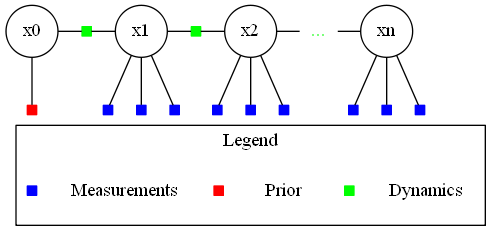

Let's define some parameters for the system

clearvars;
%Parameters for the system
dt = .1;
N = 600; %Number of time steps, each dt long

%Landmark_locations
nl = 3;
%For now, randomly distribute the landmarks over 50m box centered at (0,0)
ll = rand(2,nl)*50-25;

%control commands
V_command = [1*ones(5/dt,1); 2*ones(3/dt,1)];  %Alternate at 1m/s for 5 seconds, then 2 m/s for 3 seconds
w_command = [zeros(5/dt, 1); pi/6 * ones(3/dt,1)]; %Don't turn for 5 seconds, then turn 90 degrees in 3 seconds

%Uncorrupted initialization
x0 = [0;0;pi/2];

%Uncertainties
S0 = diag([1,1,pi/8]);%Everything usually is easier if you use the square root of the covariance matrices.  Thus "S"
sQ = diag([.1, .1, .01]);
sR = diag(1); %Assume the same from all landmarks...(

%for the factor graph, I need the inverse transpose of the cholesky...
i_S0 = inv(S0).';

%Q needs to be scaled by dt (and then inverted)
Q = sQ.' * sQ;
sQdt = sQ * sqrt(dt);
i_sQdt = inv(sQdt).';

i_sR = inv(sR).';


Now, let's generate the true trajectory.  

true_x = zeros(3,N+1);
curr_x = x0 + S0.' * randn(3,1);
true_x(:,1) = curr_x;

meas = zeros(nl,N);  %This indexing gets tricky as there are no measurements the first time step,
% so 1->N is for true_x 2 -> N+1
for ii=1:N
    V = repeatedControl(V_command, ii);
    w = repeatedControl(w_command, ii);
    curr_x = dynamics(curr_x, V, w, dt);
    curr_x = curr_x + sQdt.' * randn(3,1);
    true_x(:,ii+1) = curr_x;
    for jj=1:nl
        true_range = h( curr_x(1:2), ll(:,jj) );
        meas(jj,ii) = true_range + sR.' * randn(1);
    end
end


The state vector for the factor graph is x across all time.  Let me first initialize it with command inputs only...

%constant for indexing into fg_x
x_size =3;

fg_x = zeros(x_size*(N+1),1);  %fg_ = factor graph
fg_x(1:x_size) = x0;
curr_x = x0;
for ii=1:N
    V = repeatedControl(V_command, ii);
    w = repeatedControl(w_command, ii);
    curr_x = dynamics(curr_x, V, w, dt);
    fg_x(ii*x_size+1 : (ii+1)*x_size) = curr_x;
end
state_store(:,1) = fg_x;

### Factor graph to solve this system

To compute the factor graph, we need to create a "J" matrix and the residual matrix repeatedly for a Gauss Newton optimzation.  I am organizing this residual vector to have all the measurements followed by all the dynamics.

%Convergence criteria
max_iters = 50;
min_diff = 1E-7 * N* 3;
curr_iter = 1;
iter_cont = true;

%How big will the residual vector be?
y = zeros(numel(meas)+N*x_size + 3,1);
x_start = numel(meas)+1;

while iter_cont
    %%Create the residual vector

    % First, measurements
    pred_meas = zeros(nl, N);
    for ii=1:N
        for jj=1:nl
            pred_meas(jj,ii) = h( fg_x(ii*x_size+1:ii*x_size+2), ll(:,jj) );
        end
    end
    %This line only works because i_sR is a scalar.  Each measurement needs
    %to be individually multiplied by i_sR
    y(1:numel(meas)) = i_sR * (meas(:) - pred_meas(:));
    

    % Second, initialization of x
    y(x_start:x_start + x_size - 1) = i_S0 * (x0 - fg_x(1:x_size));
    
    % Third, dynamics (measurement is x_{t+1} - f(x_t))
    for ii=1:N
        V = repeatedControl(V_command, ii);
        w = repeatedControl(w_command, ii);
        %if the state at time ii was completely correct, what would the
        %next state be according to the dynamics
        pred_x = dynamics( fg_x((ii-1)*x_size +1 : ii*x_size), V, w, dt );
        %what the state vector currently has
        next_x = fg_x(ii*x_size + 1 : (ii+1)*x_size);
        %Handle angle wrapping...
        if (next_x(3) - pred_x(3)) < -pi
            next_x(3) = next_x(3)+2*pi;
        end
        if (next_x(3) - pred_x(3)) > pi
            next_x(3) = next_x(3)-2*pi;
        end
        %Add to the residual vector
        y( x_start+ ii*x_size : x_start+ (ii+1)*x_size -1) = i_sQdt * (next_x - pred_x);
    end
    
    %%Create J
    
    %How many non-zeros are there in the array?
    meas_num = 2; %2 elements of x affected per measurement
    dynamics_num = 8; %8 elements of fg_x affected per dynamics update
    prior_num = nnz(i_S0);
    J = spalloc(length(y), length(fg_x), meas_num*N+dynamics_num*N+prior_num);
    %Create the measurement derivatives
    for ii=1:N
        tmp_mat = zeros(nl, x_size);
        for jj=1:nl
            range = h( fg_x(ii*x_size+1:(ii+1)*x_size), ll(:,jj) );
            tmp_mat(jj,1) = (fg_x(ii*x_size+1)-ll(1,jj)) / range;
            tmp_mat(jj,2) = (fg_x(ii*x_size+2)-ll(2,jj)) / range;
        end
        tmp_mat = i_sR * tmp_mat;  %Normalize for the covariance
        J( (ii-1)*nl +1: ii*nl, ii*x_size+1 : (ii+1)*x_size ) = tmp_mat; 
    end
    %Prior derivatives:
    J(x_start:x_start+x_size-1, 1:x_size) = i_S0;
    %Derivatives due to the dynamics...
    d_start = x_start+x_size;
    for ii=1:N
        %derivatives of "next_x"
        tmp_mat = zeros(x_size,2*x_size);
        tmp_mat(:,x_size+1:end) = -eye(x_size);
        %derivatives of "pred_x"
        V = repeatedControl(V_command, ii);
        w = repeatedControl(w_command, ii);      
        tmp_mat(:,1:x_size) = [1 0 -sin(fg_x( ii*x_size ) + w/2)*V*dt; 0 1 cos(fg_x( ii*x_size ) + w/2)* V*dt; 0 0 1];
        tmp_mat = i_sQdt * tmp_mat;
        J(d_start+ (ii-1)*x_size:d_start+ii*x_size-1, (ii-1)*x_size+1:(ii+1)*x_size) = tmp_mat;
    end
    
    %Now compute the delta_x
    delta_x = zeros(size(fg_x));
    [C,R,e] = qr(J,y,'vector'); %QR with 'vector' does less fill-in for more efficiency
    delta_x(e) = R\C;  %Efficient back-substitution
    fg_x = fg_x + delta_x;   
    %Evaluate convergence criteria
    curr_iter = curr_iter+1
    norm(delta_x)
    state_store(:,curr_iter+1) = fg_x;
    iter_cont = curr_iter < max_iters & norm(delta_x) > min_diff;
end

curr_iter = 2

ans = 77.4210

curr_iter = 3

ans = 16.2469

curr_iter = 4

ans = 1.7482

curr_iter = 5

ans = 0.5275

curr_iter = 6

ans = 0.1570

curr_iter = 7

ans = 0.0448

curr_iter = 8

ans = 0.0125

curr_iter = 9

ans = 0.0035

curr_iter = 10

ans = 9.7334e-04

curr_iter = 11

ans = 2.7104e-04

curr_iter = 12

ans = 7.5468e-05

Now to do something to show how well it worked...

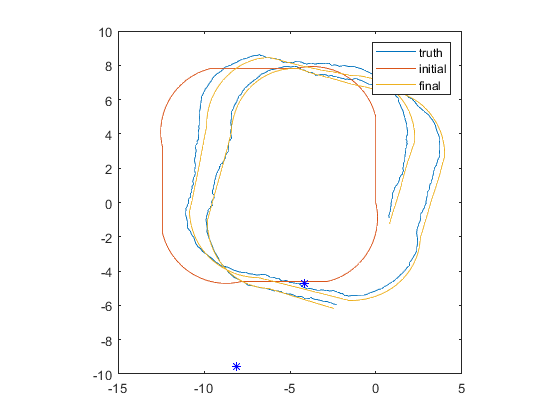

figure;
plot(true_x(1,:), true_x(2,:));
hold on; plot(state_store(1:x_size:end,1), state_store(2:x_size:end, 1));
plot(fg_x(1:x_size:end), fg_x(2:x_size:end));
plot(ll(:,1),ll(:,2),'b*')
legend('truth', 'initial', 'final')
axis square

## Example 2

This example extends example #1 but does two new things.  First, there is now a bias in the dynamics that always offsets the angular momentum.   This bias is assumed to be constant (same at all times).  One of the landmarks is also assumed to be at an unknown position at the beginning of the simulation, so it also has to estimate the landmark location.  I also extend the landmark locations to time 0.  This leads to the following graph:

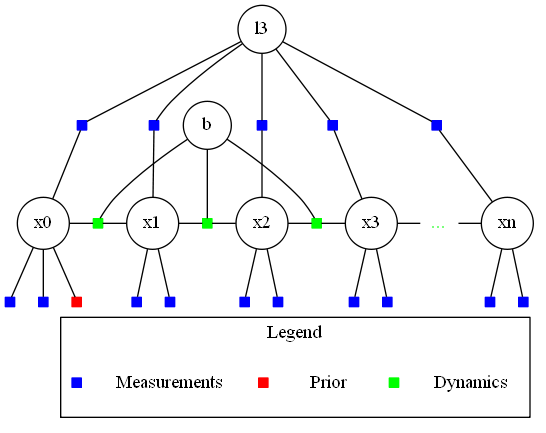

We will follow essentially the same steps as above, but the J and y functions will end up being a bit different.  fg2_x has to be modified to hold the extra states as well.

#### True Trajectory generation

bias = randn * 0.03;
true_x = zeros(3,N+1);
curr_x = x0 + S0.' * randn(3,1);
true_x(:,1) = curr_x;

meas = zeros(nl,N+1); 
for jj=1:nl
    true_range = h( curr_x(1:2), ll(:,jj) );
    meas(jj,1) = true_range + sR.' * randn(1);
end
%This indexing gets tricky as there are no measurements the first time step,
% so 1->N is for true_x 2 -> N+1
for ii=1:N
    V = repeatedControl(V_command, ii);
    w = repeatedControl(w_command, ii);
    curr_x = dynamics(curr_x, V, w, dt, bias);
    curr_x = curr_x + sQdt.' * randn(3,1);
    true_x(:,ii+1) = curr_x;
    for jj=1:nl
        true_range = h( curr_x(1:2), ll(:,jj) );
        meas(jj,ii+1) = true_range + sR.' * randn(1);
    end
end


#### Initialize the state:

%constant for indexing into fg2_x
x_start = 4;  %fg2_x(1) is the bias %fg2_x(2:3) is the landmark (three) location.  
bias_loc = 1;
lm3_loc = 2:3;
x_size =3;

fg2_x = zeros(x_size*(N+1) + 3,1);  %fg2_ = factor graph (2 for example 2)
fg2_x(lm3_loc) = 25;

fg2_x(x_start : x_start+x_size-1) = x0;
curr_x = x0;
for ii=1:N
    V = repeatedControl(V_command, ii);
    w = repeatedControl(w_command, ii);
    curr_x = dynamics(curr_x, V, w, dt); %Assuming 0 bias
    fg2_x(ii*x_size + x_start : (ii+1)*x_size + x_start-1) = curr_x;
end
state2_store(:,1) = fg2_x;

### Factor graph to solve this system

To compute the factor graph, we need to create a "J" matrix and the residual matrix repeatedly for a Gauss Newton optimzation.  I am organizing this residual vector to have all the measurements followed by all the dynamics.  Looks like this system is a bit more non-linear, so I will move the "computeY" function outside.

%Convergence criteria
max_iters = 50;
min_diff = 1E-7 * N* 3;
curr_iter = 0;
iter_cont = true;

%How big will the residual vector be?
d_start = numel(meas)+1 + x_size;
y=computeY(fg2_x, meas, x0, V_command, w_command, dt, N, x_size, x_start, d_start, ll, bias_loc, lm3_loc, i_sR, i_S0, i_sQdt);

while iter_cont
    %%I assume the current Y was always computed in the previous loop...
    %%Create J
    
    %How many non-zeros are there in the array?
    meas_num = 2; %2 elements of x affected per measurement
    dynamics_num =11; %11 elements of fg2_x affected per dynamics update, includes bias effects on dynamics
    prior_num = nnz(i_S0);
    %2*(N+1) is number of landmark 3 factor effects
    J = spalloc(length(y), length(fg2_x), meas_num*(N+1)+dynamics_num*N+prior_num+2*(N+1)); 
    %Create the measurement derivatives
    for ii=1:N+1
        tmp_mat = zeros(nl, x_size);
        for jj=1:nl-1
            range = h( fg2_x((ii-1)*x_size + x_start:ii*x_size + x_start -1), ll(:,jj) );
            tmp_mat(jj,1) = (fg2_x((ii-1)*x_size + x_start)-ll(1,jj)) / range;
            tmp_mat(jj,2) = (fg2_x((ii-1)*x_size+1 + x_start)-ll(2,jj)) / range;
        end
        range = h( fg2_x((ii-1)*x_size + x_start:ii*x_size + x_start-1), fg2_x(lm3_loc));
        tmp_mat(3,1) = (fg2_x((ii-1)*x_size + x_start) - fg2_x(lm3_loc(1)))/range;
        tmp_mat(3,2) = (fg2_x((ii-1)*x_size+1 + x_start) - fg2_x(lm3_loc(2)))/range;
        tmp_mat = i_sR * tmp_mat;  %Normalize for the covariance
        J( (ii-1)*nl +1: ii*nl, (ii-1)*x_size + x_start : ii*x_size + x_start -1 ) = tmp_mat; 
        %And for the landmark loc
        J(ii*nl, lm3_loc) = -tmp_mat(3,1:2);
    end
    %Prior derivatives:
    J(d_start-x_size:d_start-1, x_start : x_start+x_size-1) = i_S0;
    %Derivatives due to the dynamics...
    for ii=1:N
        %derivatives of "next_x"
        tmp_mat = zeros(x_size,2*x_size);
        tmp_mat(:,x_size+1:end) = -eye(x_size);
        %derivatives of "pred_x"
        V = repeatedControl(V_command, ii);
        w = repeatedControl(w_command, ii);      
        tmp_mat(:,1:x_size) = [1 0 -sin(fg2_x( (ii-1)*x_size+ x_start+2 ) + (w+fg2_x(bias_loc))/2)*V*dt; 0 1 cos(fg2_x( (ii-1)*x_size+ x_start+2 ) + (w+fg2_x(bias_loc))/2)* V*dt; 0 0 1];
        tmp_mat = i_sQdt * tmp_mat;
        J(d_start+ (ii-1)*x_size:d_start+ii*x_size-1, (ii-1)*x_size + x_start:(ii+1)*x_size + x_start-1) = tmp_mat;
        %What effect does the bias have?
        tmp_bias_deriv = dt*[-sin(fg2_x( (ii-1)*x_size+ x_start+2 ) + (w+fg2_x(bias_loc))/2)*V/2;...
            cos(fg2_x( (ii-1)*x_size+ x_start+2 ) + (w+fg2_x(bias_loc))/2)* V/2; 1];
        J(d_start+ (ii-1)*x_size: d_start+ii*x_size-1, bias_loc) = i_sQdt*tmp_bias_deriv;
    end
    
    %Now compute the delta_x
    delta_x = zeros(size(fg2_x));
    [C,R,e] = qr(J,y,'vector'); %QR with 'vector' does less fill-in for more efficiency
    delta_x(e) = R\C;  %Efficient back-substitution
    cand_x = fg2_x + delta_x;   
    %Do a test for how well the derivative fits the cost function.  Scale
    %the length of delta_x down until it works
    old_cost = y.' * y;
    new_y = computeY(cand_x, meas, x0, V_command, w_command, dt, N, x_size, x_start, d_start, ll, bias_loc, lm3_loc, i_sR, i_S0, i_sQdt);
    new_cost = new_y.' * new_y;
    linear_y = y - J * delta_x;
    linear_cost = linear_y.' * linear_y;
    ratio = (old_cost-linear_cost) / (old_cost - new_cost);
    while ratio < .25 || ratio > 4 %This statement did nothing to solve the "converge to the wrong bias" problem
        disp('Scaling down delta x');
        delta_x = delta_x / 2.0;
        cand_x = fg2_x + delta_x;
        new_y = computeY(cand_x, meas, x0, V_command, w_command, dt, N, x_size, x_start, d_start, ll, bias_loc, lm3_loc, i_sR, i_S0, i_sQdt);
        new_cost = new_y.' * new_y;
        linear_y = y - J * delta_x;
        linear_cost = linear_y.' * linear_y;
        ratio = (old_cost-linear_cost) / (old_cost - new_cost);        
    end
    fg2_x = cand_x;
    y= new_y;
    %Evaluate convergence criteria
    curr_iter = curr_iter+1
    norm(delta_x)
    state2_store(:,curr_iter+1) = fg2_x;
    iter_cont = curr_iter < max_iters & norm(delta_x) > min_diff;
end

Scaling down delta x


curr_iter = 1

ans = 67.4849

curr_iter = 2

ans = 98.4957

curr_iter = 3

ans = 134.1226

curr_iter = 4

ans = 67.8686

curr_iter = 5

ans = 16.9447

curr_iter = 6

ans = 8.1541

curr_iter = 7

ans = 28.8226

curr_iter = 8

ans = 43.4483

curr_iter = 9

ans = 11.3360

curr_iter = 10

ans = 1.3886

curr_iter = 11

ans = 0.1469

curr_iter = 12

ans = 0.0157

curr_iter = 13

ans = 0.0048

curr_iter = 14

ans = 6.6489e-04

curr_iter = 15

ans = 1.9747e-04

curr_iter = 16

ans = 3.1931e-05

### Results:

Let's check and see how well we estimate bias

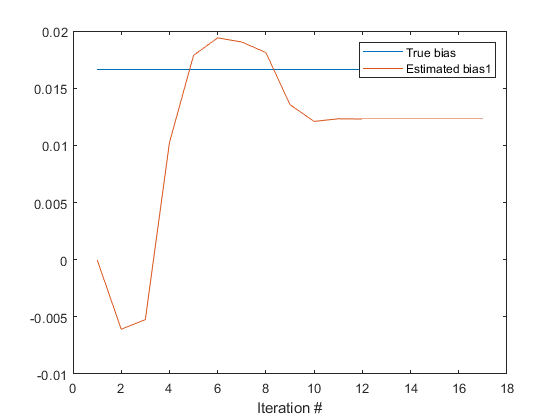

figure;
plot(1:size(state2_store,2), ones(1,size(state2_store,2))*bias);
hold on; plot(state2_store(bias_loc,:));
% plot(state2_store(bias_loc+1,:));
legend('True bias', 'Estimated bias1');
xlabel('Iteration #');

How about the location of the landmark?

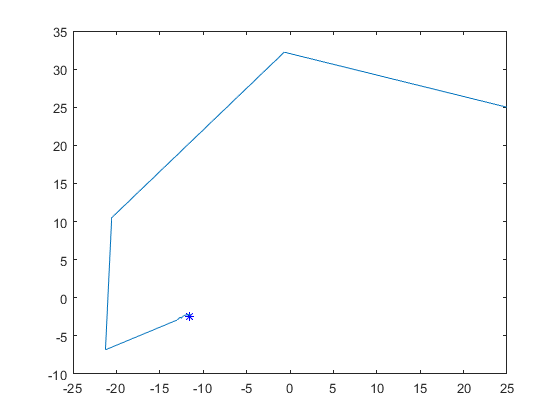

figure;
plot(ll(1,3), ll(2,3),'b*')
hold on; plot(state2_store(lm3_loc(1),:), state2_store(lm3_loc(2),:))

xlim('auto')
ylim('auto')

And the overall path

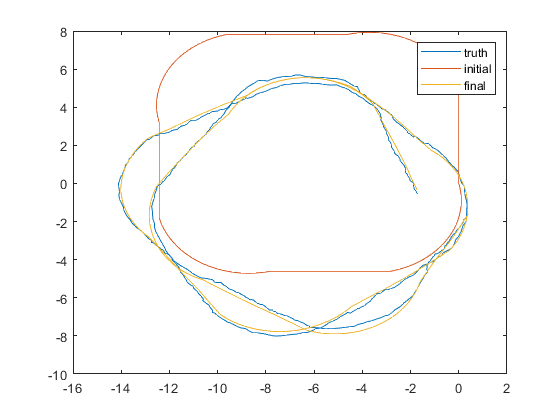

figure;
plot(true_x(1,:), true_x(2,:));
hold on; plot(state2_store(x_start:x_size:end,1), state2_store(x_start+1:x_size:end, 1));
plot(fg2_x(x_start:x_size:end), fg2_x(x_start+1:x_size:end));
legend('truth', 'initial', 'final')

ll

ll =    -8.0914   -9.5418  -11.5785
   -4.1783   -4.7436   -2.4606


## Functions for implementing systems above

First, let's define a function for the dynamics

function next_x = dynamics(curr_x, V, w, dt, bias)
    if ~exist('bias','var')
        bias = 0;
    end
    next_x = curr_x + [V * cos(curr_x(3)+(w+bias)/2.0); V * sin(curr_x(3)+(w+bias)/2.0); (w + bias)] * dt;
end

Second, a function for the measurements.  

function meas = h(curr_x, landmark_loc)
    meas = norm(curr_x(1:2) - landmark_loc);
end

A quick helper function for indexing

function control = repeatedControl(vector, time)
    control = vector(mod(time-1,length(vector))+1);
end

This one is just for the second system

function y = computeY(fg2_x, meas, x0, V_command, w_command, dt, N, x_size, x_start, d_start, ll, bias_loc, lm3_loc, i_sR, i_S0, i_sQdt)
    nl =size(meas, 1);
    y = zeros(numel(meas)+N*x_size+x_size,1);
    % First, measurements
    pred_meas = zeros(nl, N+1);
    for ii=1:N+1
        for jj=1:nl
            if jj~=3
                pred_meas(jj,ii) = h( fg2_x((ii-1)*x_size + x_start: (ii-1)*x_size+1 + x_start), ll(:,jj) );
            else
                pred_meas(jj,ii) = h(fg2_x((ii-1)*x_size + x_start: (ii-1)*x_size+1+x_start), fg2_x(lm3_loc));
            end
        end
    end
    %This line only works because i_sR is a scalar.  Each measurement needs
    %to be individually multiplied by i_sR
    y(1 : numel(meas)) = i_sR * (meas(:) - pred_meas(:));  

    % Second, initialization of x
    y(d_start-x_size:d_start - 1) = i_S0 * (x0 - fg2_x(x_start+(0:x_size-1)));
    
    % Third, dynamics (measurement is x_{t+1} - f(x_t))
    for ii=1:N
        V = repeatedControl(V_command, ii);
        w = repeatedControl(w_command, ii);
        %if the state at time ii was completely correct, what would the
        %next state be according to the dynamics
        pred_x = dynamics( fg2_x((ii-1)*x_size + x_start : ii*x_size + x_start -1), V, w, dt, fg2_x(bias_loc) );
        %what the state vector currently has
        next_x = fg2_x(ii*x_size +x_start : (ii+1)*x_size + x_start - 1);
        %Handle angle wrapping...
        if (next_x(3) - pred_x(3)) < -pi
            next_x(3) = next_x(3)+2*pi;
        end
        if (next_x(3) - pred_x(3)) > pi
            next_x(3) = next_x(3)-2*pi;
        end
        %Add to the residual vector
        y( d_start+ (ii-1)*x_size : d_start + ii*x_size -1) = i_sQdt * (next_x - pred_x);
    end
end

This bit of code is nice for testing the derivatives out.  I run it on a breakpoint after J has been computed...

% for ii=1:length(fg2_x)
%     idx_test=ii;
%     fg2_tst = fg2_x;
%     fg2_tst(idx_test) = fg2_tst(idx_test)+.001;
%     y_tst=computeY(fg2_tst, meas, x0, V_command, w_command, dt, N, x_size, x_start, d_start, ll, bias_loc, lm3_loc, i_sR, i_S0, i_sQdt);
%     num_J_col = (y_tst - y)/.001;
%     max_diff(ii) = max(abs(num_J_col + J(:,idx_test)));
% end